If tissueID = 0 - voxel is air
If tissueID = 1 - voxel is skin
If tissueID = 2 - voxel is skull
If tissueID = 3 - voxel is cerebrospinal fluid
If tissueID = 4 - voxel is grey matter
If tissueID = 5 - voxel is cerebellum
If tissueID = 6 - voxel is white matter
If tissueID = 7 - voxel is ventricles

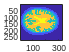

load 103111.mat;
brain_slice_1 = tissueMatrix(:,: ,136);
c_slice = brain_slice_1;
rho_slice = brain_slice_1;
imagesc(brain_slice_1);

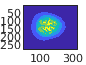

for i = 50:200
    brain_slice = tissueMatrix(:,:,i);
    pause(.1);
    imagesc(brain_slice);

end

c_slice(c_slice == 0) = 1500;
c_slice(c_slice == 1) = 1624;
c_slice(c_slice == 2) = 2814;
c_slice(c_slice == 3) = 1504;
c_slice(c_slice == 4) = 1505;
c_slice(c_slice == 5) = 1537;
c_slice(c_slice == 6) = 1553;
c_slice(c_slice == 7) = 1505;

rho_slice(rho_slice == 0) = 1020;
rho_slice(rho_slice == 1) = 1020;
rho_slice(rho_slice == 2) = 1908;
rho_slice(rho_slice == 3) = 4;
rho_slice(rho_slice == 4) = 1045;
rho_slice(rho_slice == 5) = 400;
rho_slice(rho_slice == 6) = 1042;
rho_slice(rho_slice == 7) = 1007;

brain_slice_1 = flip(brain_slice_1');;
c_slice = flip(c_slice',1);
rho_slice = flip(rho_slice',1);


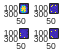

subplot(2,2,1);
imagesc(brain_slice_1);
subplot(2,2,2);
imagesc(c_slice);
subplot(2,2,3);
imagesc(rho_slice);
subplot(2,2,4);
imagesc(c_slice.*rho_slice);

lambda = 2e-4

lambda = 2.0000e-04

tscan = ScanCartesian('x', [-30e-3:lambda/4:30e-3],'z',[0:lambda/8:80e-3]);

tscan2 = ScanCartesian('x', linspace(-30e-3,30e-3,280),'z',linspace(0, 80e-3,330))

tscan2 =   ScanCartesian with properties:

        x: [-0.0300 -0.0298 -0.0296 -0.0294 -0.0291 -0.0289 -0.0287 -0.0285 -0.0283 -0.0281 -0.0278 -0.0276 -0.0274 -0.0272 -0.0270 -0.0268 -0.0266 -0.0263 -0.0261 -0.0259 -0.0257 -0.0255 -0.0253 -0.0251 -0.0248 -0.0246 -0.0244 -0.0242 -0.0240 … ]
        y: 0
        z: [0 2.4316e-04 4.8632e-04 7.2948e-04 9.7264e-04 0.0012 0.0015 0.0017 0.0019 0.0022 0.0024 0.0027 0.0029 0.0032 0.0034 0.0036 0.0039 0.0041 0.0044 0.0046 0.0049 0.0051 0.0053 0.0056 0.0058 0.0061 0.0063 0.0066 0.0068 0.0071 0.0073 0.0075 … ]
    order: 'ZXY'
     size: [330 280 1]
       xb: [-0.0300 0.0300]
       yb: [0 0]
       zb: [0 0.0800]
     nPix: 92400
       dx: 2.1505e-04
       dy: Inf
       dz: 2.4316e-04


med_temp = Medium.Sampled(tscan2, c_slice,rho_slice);

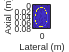

figure;
h = imagesc(med_temp,tscan,'c');

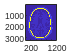

figure;imagesc(imgaussfilt(h.CData))

figure;imagesc(imgaussfilt3(h.CData))

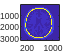

figure;imagesc(imgaussfilt(h.CData,[4 1]))

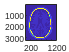

h_filt =   Image with properties:

           CData: [3201×1201 double]
    CDataMapping: 'scaled'

  Show all properties


figure;
h_filt =imagesc(imgaussfilt(h.CData,[1 4]))

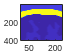

itis_c_slice = h_filt.CData(2686:3085, 436:675);
itis_c_slice = flip(itis_c_slice,1);
%itis_c_slice(1:20,:) = itis_c_slice(20,150);
imagesc(itis_c_slice);

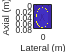

rhoh = imagesc(med_temp,tscan,'rho');

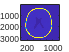

rho_filt =   Image with properties:

           CData: [3201×1201 double]
    CDataMapping: 'scaled'

  Show all properties


rho_filt =imagesc(imgaussfilt(rhoh.CData,[1 4]))

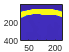

itis_rho_slice = rho_filt.CData(2686:3085, 436:675);
itis_rho_slice = flip(itis_rho_slice,1);
%itis_rho_slice(1:20,:) = itis_rho_slice(20,150);
imagesc(itis_rho_slice);

save('ITIS_crho_slice', 'itis_c_slice','itis_rho_slice');
